# Final Project  r11521212 鄭傳嶧

collaborate with r11521201 廖沁柔

clc;clear;close all;
opengl hardware;

input data

data = importdata('Final Project 3-story-with Abrup tReduction Column Stiffness.txt');

set up parameters

time = data.data(:,1);  % seconds

input = data.data(:,2);  % accel (gal) % base
for i = 1:3
    story(:,i) = data.data(:,i+2); % accel (gal)
end

SR = 50;  % Hz
dt = 1/SR; % seconds
L = length(time) ; % length of the signal

### (1)

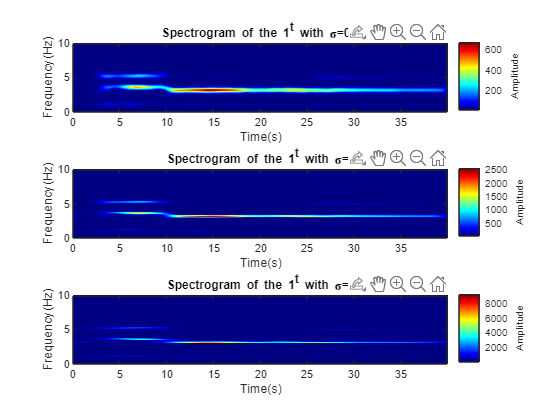

sigma = [0.5;1;2];
f_range = 0:0.01:10;
str = '1^s^t';
MCMW_VCF_2(time,story(:,1),sigma,dt,f_range,str);

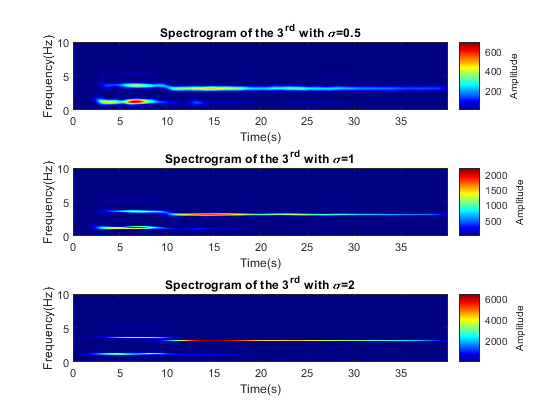

str = '3^r^d';
MCMW_VCF_2(time,story(:,3),sigma,dt,f_range,str);

### (2)

analysis data (0.0sec - 9.5sec)

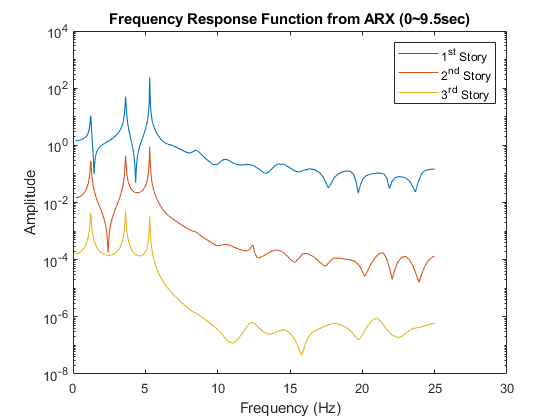

index = find(time>=9.5, 1);
input2 = input(1:index);
figure()
for i=1:3
    output(:,i) = story(1:index,i);
    na= 30; nb = 30; % user-defined
    [freq,damping]=ARX_model(input2,output(:,i),SR,na,nb,i);
end
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Frequency Response Function from ARX (0~9.5sec)')
legend('1^s^t Story','2^n^d Story','3^r^d Story')

### (3)

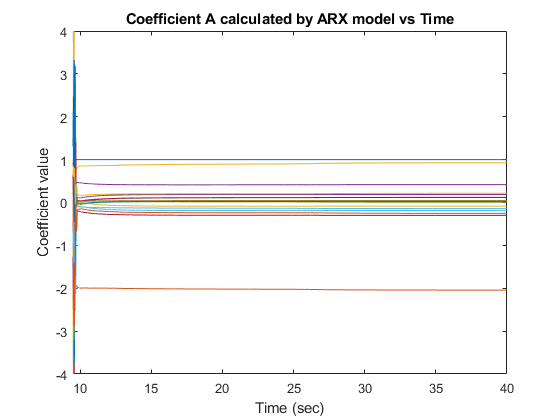

for i = 1:3
    story2(:,i) = story(index:L,i); % 9.5秒之後
end
input3 = input(index:L);
nn = [16 16 0];
obj = recursiveARX(nn);
A1 = zeros(L,nn(1)+1);
B1 = zeros(L,nn(2));
A2 = zeros(L-index+1,nn(1)+1);
B2 = zeros(L-index+1,nn(2));
for i = 1:L
    [A1(i,:),B1(i,:),outputdata] = step(obj,story(i,3),input(i));
end

for i = 1:L-index+1
    [A2(i,:),B2(i,:),outputdata] = step(obj,story2(i,2),input3(i));
end
% figure()
% plot(time,A1)
% figure()
% plot(time,B1)
figure()
plot(time(index:L),A2)
xlim([9.5 40]);
ylim([-4 4]);
xlabel('Time (sec)')
ylabel('Coefficient value')
title('Coefficient A calculated by ARX model vs Time')

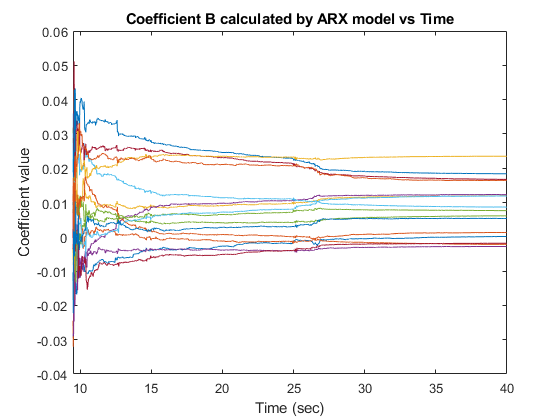


figure()
plot(time(index:L),B2)
xlim([9.5 40]);
%ylim([-0.04 0.04]);
xlabel('Time (sec)')
ylabel('Coefficient value')
title('Coefficient B calculated by ARX model vs Time')

### (4)

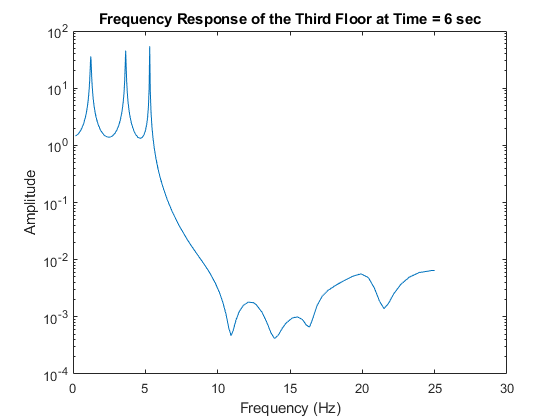

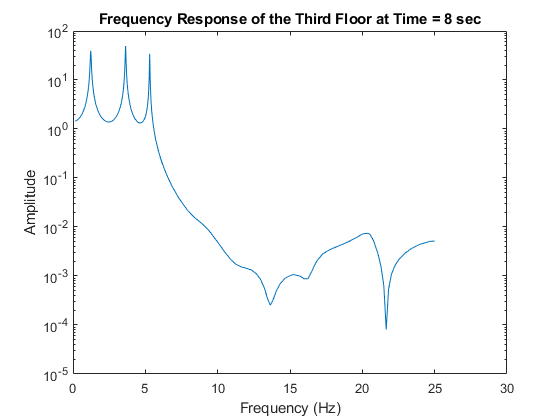

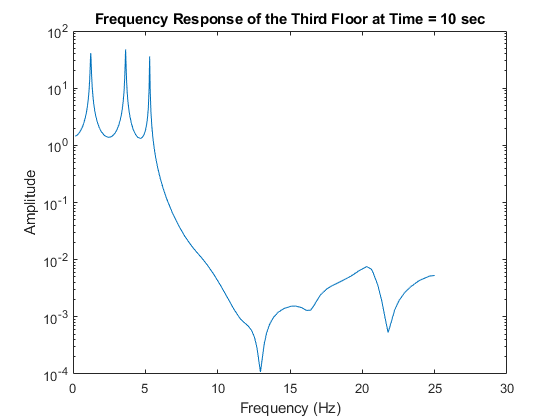

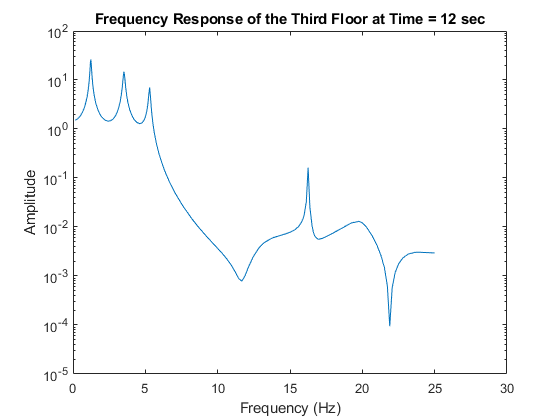

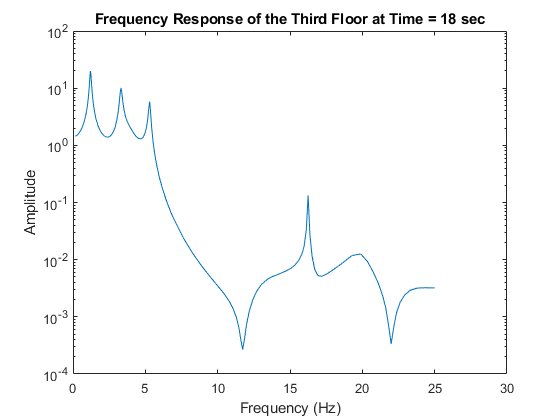

t = [6 8 9.5 12 18];
for i =1:5
    sys = idpoly(A1(t(i)*SR+1,:),B1(t(i)*SR+1,:),[],[],[],[],dt);
    [mag, phase, wd] = ffplot(sys);
    magnitude = reshape(mag,1,[]);
    figure()
    semilogy(wd,magnitude);
    xlabel('Frequency (Hz)')
    ylabel('Amplitude')
    title(['Frequency Response of the Third Floor at Time = ', int2str(t(i)), ' sec'])
end